Уточнение по Ричардсону

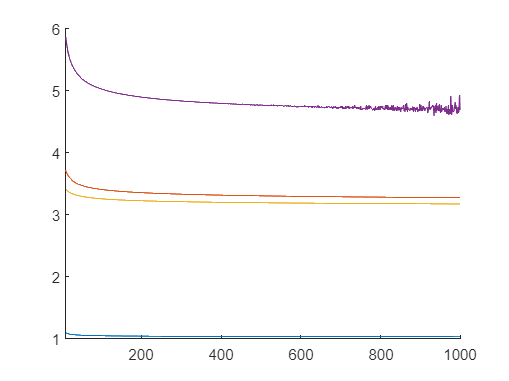

for n = 10:1:1000
    x_testrh = linspace(begin, ending ,n);
    x_testrh2 = linspace(begin, ending ,2*n);
    
    int_h = left_rectangle(x_testrh, fun);
    int_h2 = left_rectangle(x_testrh2, fun);
   
    Int = (2^2*int_h2-int_h)/(2^2-1);

    deviath = abs(integral(fun, begin, ending) - Int);
    alphh1(n) = -log(deviath)/log(length(x_testrh));
end

for n = 10:1:1000
    x_testrh = linspace(begin, ending ,n);
    x_testrh2 = linspace(begin, ending ,2*n);
    
    int_h = mid_rectangle(x_testrh, fun);
    int_h2 = mid_rectangle(x_testrh2, fun);
   
    Int = (2^2*int_h2-int_h)/(2^2-1);

    deviath = abs(integral(fun, begin, ending) - Int);
    alphh2(n) = -log(deviath)/log(length(x_testrh));
end

for n = 10:1:1000
    x_testrh = linspace(begin, ending ,n);
    x_testrh2 = linspace(begin, ending ,2*n);
    
    int_h = trapezoid(x_testrh, fun);
    int_h2 = trapezoid(x_testrh2, fun);
   
    Int = (2^2*int_h2-int_h)/(2^2-1);

    deviath = abs(integral(fun, begin, ending) - Int);
    alphh3(n) = -log(deviath)/log(length(x_testrh));
end

for n = 10:1:1000
    x_testrh = linspace(begin, ending ,n);
    x_testrh2 = linspace(begin, ending ,2*n);
    
    int_h = Simpson(x_testrh, fun);
    int_h2 = Simpson(x_testrh2, fun);
   
    Int = (2^2*int_h2-int_h)/(2^2-1);

    deviath = abs(integral(fun, begin, ending) - Int);
    alphh4(n) = -log(deviath)/log(length(x_testrh));
end

hold on
plot(alphh1)
plot(alphh2)
plot(alphh3)
plot(alphh4)
xlim([10 1000])